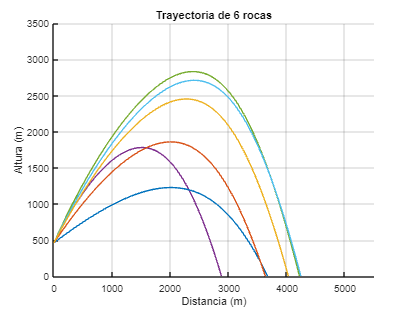

%Limpieza de valores
clc;
clear vars;
close all;

%Pedir # de rocas a simular

num_rocas = input("Ingresa el # de rocas a simular: ");

%Datos iniciales
dt = 0.3; %puntos
gravedad = -9.81; %Gravedad
masa = 1580.8;
densidad_aire = 1.29; %Densidad del aire
cd = 1.65; %Coeficiente de resistencia de la roca vs aire
xo = 0; %posición inicial en x
yo = 463; %altura en y inicial
limitex = 0;
limitey = 0;

for i = 1:num_rocas
    theta(i) = randi([30,70]); %Ángulo
    Vi(i) = randi([100,300]); %Velocidad inicial
    vxo = Vi(i) * cosd(theta(i)); %Componente X velocidad
    vyo = Vi(i) * sind(theta(i)); %Componente Y velocidad
    densidad_rock = randi([2600,2900]); %Densidad de roca
    radio = ((masa/densidad_rock)*(3/4)/pi)^(1/3); %Radio de la roca
    area = pi * radio^2; %Area transversal
    b = 0.5 .* densidad_aire .* cd .* area;  % Resisitencia del aire

    %Arreglos x/y/Vy/Vx/ac/ay
    x = [];
    y = [];
    Vy = [];
    Vx = [];
    ax = [];
    ay = [];
    
    %Definir valores iniciales de la aceleración
    ax(1)=0;
    ay(1)=0;
    ax(2) = 0;
    ay(2) = gravedad;

    x(2) = xo; %Posición inicial en X
    y(2) = yo; %Posición inicial en X
    x(1) = x(2) - vxo * dt; %Valor x(n - 1)
    y(1) = y(2) - vyo * dt + 0.5 * gravedad * (dt^2); %Posición y(n - 1)
   
    %Definir valores iniciales de la velocidad
    Vx(1)=0;
    Vy(1)=0;
    Vx(2) = vxo;
    Vy(2) = vyo;

   %Comienza desde 2 porque 1 es el paso (n - 1)
    ytemp=1;
    while (ytemp > 0)
        % Calcular los componentes X e Y de la aceleración
        axtemp = (-b * (Vx(end) ^ 2)) / masa;
        ax(end+1) = axtemp;
        aytemp = -(Vy(end) / abs(Vy(end)) * ((b * (Vy(end) ^ 2)) / masa)) + gravedad;
        ay(end+1) = aytemp;

        % Calcular la posición X e Y
        xtemp = 2*x(end) - x(end-1) + 0.5 * ax(end) * dt^2;
        x(end+1) = xtemp;
        ytemp = 2 * y(end) - y(end-1) + 0.5 * ay(end) * dt^2;
        y(end+1) = ytemp;

        % Calcular los componentes X e Y de la velocidad
        Vxtemp = (x(end) - x(end-1)) / dt;
        Vx(end+1) = Vxtemp;
        Vytemp = (y(end) - y(end-1)) / dt;
        Vy(end+1) = Vytemp;
        % Incrementar el contador j

    end
    %Animación de la trayectoria
    tituloGrafica= strcat("Trayectoria de ", num2str(num_rocas)," rocas");
    xlabel('Distancia (m)');
    ylabel('Altura (m)');
    title( tituloGrafica );
    grid on;
    xlim([0 (limitex+5500)])
    ylim([0 (limitey+3500)])
    hold on;
    comet(x, y);
    plot(x,y);
end